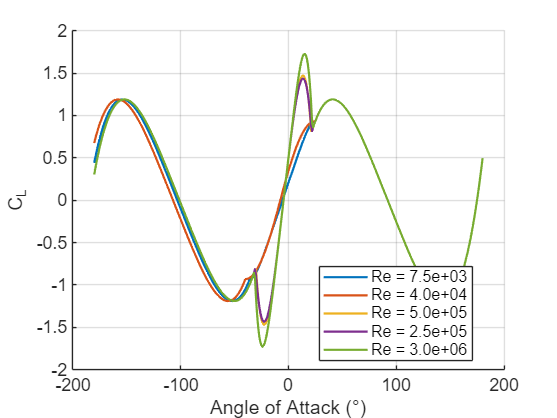

clc
clear
close all

airfoil = load('./airfoils/data/naca4412.mat').airfoil;
data = airfoil.data;

alpha = -180:1:180;
Re_values = [7.5e3 4e4 5e5 2.5e5 3e6];

cl_matrix = zeros(length(alpha), length(Re_values));
cd_matrix = zeros(length(alpha), length(Re_values));

for i = 1:length(Re_values)
    for j = 1:length(alpha)
        [cl_matrix(j, i), cd_matrix(j, i), ~] = AerodynamicModel(alpha(j), Re_values(i), data, 'false');
    end
end

figure;
hold on;
for i = 1:length(Re_values)
    plot(alpha, cl_matrix(:, i), 'LineWidth', 1.5, 'DisplayName', ['Re = ', num2str(Re_values(i), '%.1e')]);
end
hold off;
xlabel('Angle of Attack (°)');
ylabel('C_L');
legend('show', 'Location', 'best');
grid on;
set(gca, 'FontSize', 12);
saveas(gcf, "cl_naca4412", 'epsc')

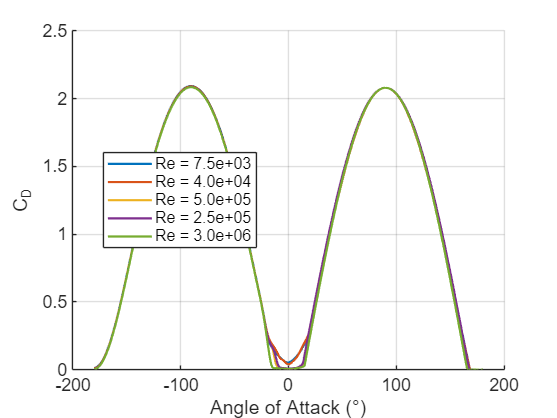

figure;
hold on;
for i = 1:length(Re_values)
    plot(alpha, cd_matrix(:, i), 'LineWidth', 1.5, 'DisplayName', ['Re = ', num2str(Re_values(i), '%.1e')]);
end
hold off;
xlabel('Angle of Attack (°)');
ylabel('C_D');
legend('show', 'Location', 'best');
grid on;
set(gca, 'FontSize', 12);
saveas(gcf, "cd_naca4412", 'epsc')